
format long
N = 400; %Number of Bernoulli Trials
x = 0:400; % NUmber os Successes
p = 0.01;

lambda = N*p; %Probability of SUccess
y = binopdf(x, N, p)%Binomial PDF in-built funrion with parameter x and p

y =    0.017950553275045   0.072527487979981   0.146153877292991   0.195856037584547   0.196350623538044   0.157080498830435   0.104455887269397   0.059387618447536   0.029468856123588   0.012964973737875   0.005120509829807   0.001833791399104   0.000600458631525   0.000181024047422   0.000050545675579   0.000013138471901   0.000003193378587   0.000000728614009   0.000000156598858   0.000000031802639   0.000000006119599   0.000000001118541   0.000000000194641   0.000000000032312   0.000000000005127   0.000000000000779   0.000000000000113   0.000000000000016   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.00000000000

z = poisspdf(x, lambda) %Poisson PDF

z =    0.018315638888734   0.073262555554937   0.146525111109873   0.195366814813165   0.195366814813165   0.156293451850532   0.104195634567021   0.059540362609726   0.029770181304863   0.013231191691050   0.005292476676420   0.001924536973244   0.000641512324415   0.000197388407512   0.000056396687861   0.000015039116763   0.000003759779191   0.000000884653927   0.000000196589762   0.000000041387318   0.000000008277464   0.000000001576660   0.000000000286665   0.000000000049855   0.000000000008309   0.000000000001329   0.000000000000205   0.000000000000030   0.000000000000004   0.000000000000001   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.00000000000

### Plotting The Probability Against The Bernoulli Trials

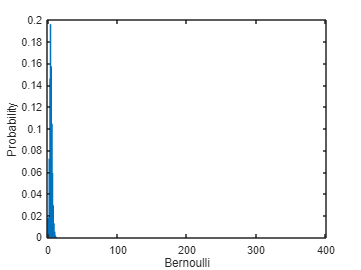

bar(x, y, 1)%Histogram of outputs
xlabel('Bernoulli')
ylabel('Probability')

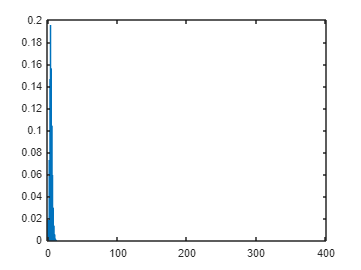

bar(x,z,1)

### Nomality Test

mu = N*p;
sigma = sqrt(mu*(1-p));
x2 = 0:0.1:N;
y2 = normpdf(x2, mu, sigma)

y2 =    0.026588870153411   0.029377826458218   0.032377457028492   0.035593369823815   0.039030020123409   0.042690549024987   0.046576623495895   0.050688280657816   0.055023779162998   0.059579460653019   0.064349624373319   0.069326418041692   0.074499748030979   0.079857211820998   0.085384055499383   0.091063158843890   0.096875050200447   0.102797952983915   0.108807865176385   0.114878672687155   0.120982296877310   0.127088875950121   0.133166979277800   0.139183853088595   0.145105695289933   0.150897956568221   0.156525664299481   0.161953765242493   0.167147482482545   0.172072681663264   0.176696241199123   0.180986420913029   0.184913223400904   0.188448742394888   0.191567492482489   0.194246714741800   0.196466653170736   0.198210797216242   0.199466086239778   0.200223072377510   0.200476038954592   0.200223072377510   0.199466086239778   0.198210797216242   0.196466653170736   0.194246714741800   0.191567492482489   0.188448742394888   0.184913223400904   0.1809864209

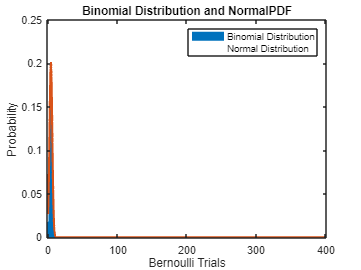

bar(x,y,1)
hold on
plot(x2, y2, 'LineWidth', 2)
xlabel('Bernoulli Trials')
ylabel('Probability')
title('Binomial Distribution and NormalPDF')
legend('Binomial Distribution','Normal Distribution')
hold off